1、画图看数据的平稳性（原始数据、一阶差分、二阶差分）

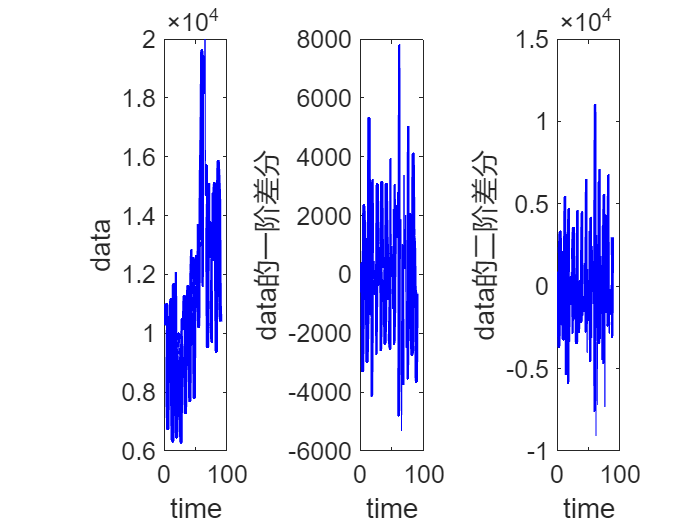

data=[10930,10318,10595,10972,7706,6756,9092,10551,9722,10913,11151,8186,6422 ...
    6337,11649,11652,10310,12043,7937,6476,9662,9570,9981,9331,9449,6773,6304,9355 ...
    10477,10148,10395,11261,8713,7299,10424,10795,11069,11602,11427,9095,7707,10767 ...
    12136,12812,12006,12528,10329,7818,11719,11683,12603,11495,13670,11337,10232 ...
    13261,13230,15535,16837,19598,14823,11622,19391,18177,19994,14723,15694,13248 ...
    9543,12872,13101,15053,12619,13749,10228,9725,14729,12518,14564,15085,14722 ...
    11999,9390,13481,14795,15845,15271,14686,11054,10395];
% clc,clear;
subplot(131)
plot(data,'b-','LineWidth',2)
xlabel('time')
ylabel('data')
set(gca,'fontsize',15)
subplot(132)
ddata = diff(data);
plot(ddata,'b-','LineWidth',2)
xlabel('time')
ylabel('data的一阶差分')
set(gca,'fontsize',15)
subplot(133)
dddata = diff(data,2);
plot(dddata,'b-','LineWidth',2)
xlabel('time')
ylabel('data的二阶差分')
set(gca,'fontsize',15)

2、数据平稳性测试

% 数据平稳性测试,adf=1 kpss=0表示通过
adftest(data)

ans = logical
   0


kpsstest(data)

ans = logical
   1


% 一阶差分并平稳性检验
ddata = diff(data);
d1_adf = adftest(ddata)

d1_adf = logical
   1


d1_kpss = kpsstest(ddata)

d1_kpss = logical
   0


3、绘制自相关与偏自相关图（此处可直接看图得出pq（牛逼的话），也可通过下面的计算方法得到）

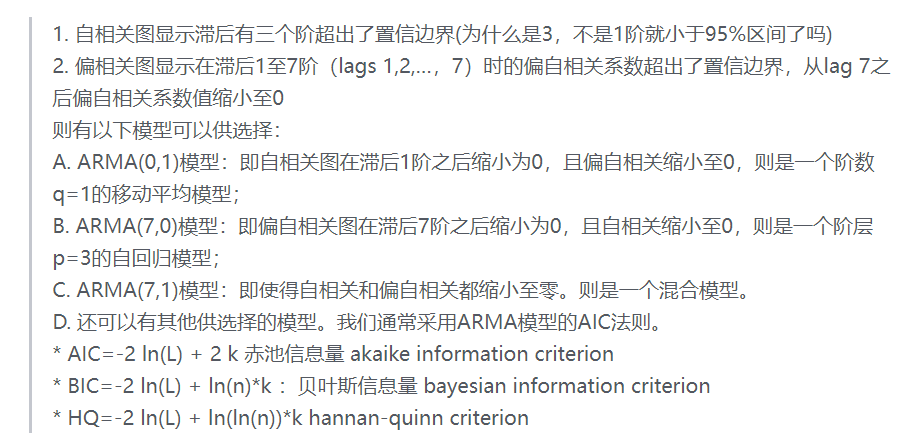

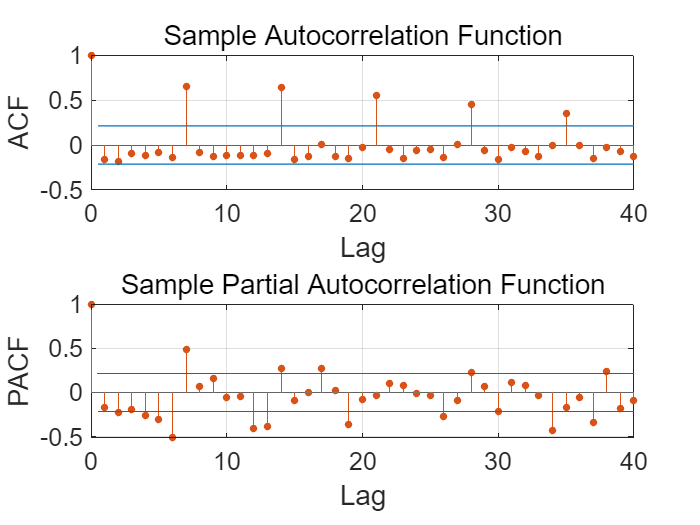

% 绘制自相关与偏自相关图
% 这里要用一阶差分之后的数据绘图
figure
subplot(211)
autocorr(ddata,40)
ylabel('ACF')
set(gca,'fontsize',15)
subplot(212)
parcorr(ddata,40)
ylabel('PACF')
set(gca,'fontsize',15)

4、计算pq，其中pmax和qmax即遍历可能的最大值（4,4的意思就是最多会到4,x,4）

%% 计算pq取值
pmax = 4;
qmax = 4;
d = 1;
%[p q ]=findPQ(data,pmax,qmax,d);

5、接下去就是构建模型

%% 构建模型
p = 3;q = 4;
Mdl = arima(p, 1, q);  %第二个变量值为1，即一阶差分
EstMdl = estimate(Mdl,data');

 
    ARIMA(3,1,4) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant            10          158.9        0.062931       0.94982
    AR{1}          0.48383        0.26764          1.8077      0.070649
    AR{2}        -0.049979        0.31408        -0.15913       0.87357
    AR{3}         -0.76235        0.25966         -2.9359     0.0033254
    MA{1}         -0.91589        0.25915         -3.5343    0.00040893
    MA{2}         -0.06313        0.29811        -0.21177       0.83229
    MA{3}           0.9576        0.27033          3.5423    0.00039666
    MA{4}         -0.51826        0.21031         -2.4642       0.01373
    Variance    5.4144e+06     0.00016994      3.1861e+10             0



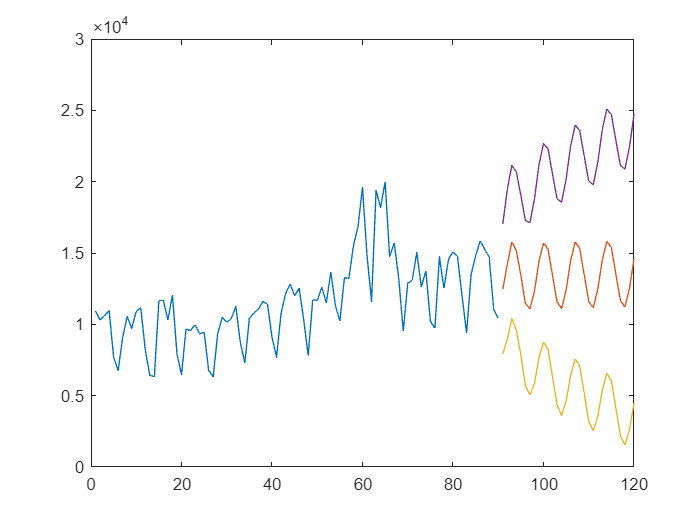

%% 模型预测
step = 30;
[forData,YMSE] = forecast(EstMdl,step,'Y0',data');  
 %matlab2018及以下版本写为Predict_Y(i+1) = forecast(EstMdl,1,'Y0',Y(1:i)); 
lower = forData - 1.96*sqrt(YMSE); %95置信区间下限
upper = forData + 1.96*sqrt(YMSE); %95置信区间上限
figure
plot(1:length(data),data)
hold on
plot((length(data)+1):length(data)+step,forData)
hold on
plot((length(data)+1):length(data)+step,lower)
plot((length(data)+1):length(data)+step,upper)

function [p q] = findPQ(data,pmax,qmax,d)
data = reshape(data,length(data),1);
LOGL=zeros(pmax+1,qmax+1);
PQ=zeros(pmax+1,qmax+1);
for p=0:pmax
    for q=0:qmax
        model=arima(p,d,q);
        [fit,~,logL]=estimate(model,data);  %指定模型的结构
        LOGL(p+1,q+1)=logL;
        PQ(p+1,q+1)=p+q;  %计算拟合参数的个数
    end
end
LOGL=reshape(LOGL,(pmax+1)*(qmax+1),1);
PQ=reshape(PQ,(pmax+1)*(qmax+1),1);
m2 = length(data);
[aic,bic]=aicbic(LOGL,PQ+1,m2);
aic0 = reshape(aic,(pmax+1),(qmax+1));
bic0= reshape(bic,(pmax+1),(qmax+1));

aic1 = min(aic0(:));
index = aic1==aic0;
[pp qq] = meshgrid(0:pmax,0:qmax);
p0 = pp(index);
q0 = qq(index);

aic2 = min(bic0(:));
index = aic2==bic0;
[pp qq] = meshgrid(0:pmax,0:qmax);
p1 = pp(index);
q1 = qq(index);

if p0^2+q0^2> p1^2+q1^2
    p = p1;
    q = q1;
else
    p = p0;
    q = q0;
end

end